%% Idea : Rather than simultaneous optimization of all three gears, assume

## Gearbox Targets

bending_safety_target = 1.2;
wear_safety_target = 1.1;
target_gr = 1.8;
gb_rad_lim = 130;
if true
    target_center_dist = 38.5;
else
    target_center_dist = 1000*(wheelbearing.internalDiameter - planetPin.diameter)/2; %#ok<*UNRCH> 
    fprintf("Target Center Distance (mm): %.2f",target_center_dist);
end
 

## Module Sweep Parameters

modulesStartVal = 0.5;
modulesIncrement = 0.05;
modulesEndVal = 1.5 ;
modules = modulesStartVal:modulesIncrement:modulesEndVal;
excludevals = 0;
if false
    openvar('excludevals');
end

    goodness    passed_modules
    ________    ______________

     4.1151           0.5     
     3.8791          0.55     
     3.6111           0.6     
     3.3089          0.65     
      3.076           0.7     
     3.0179          0.75     
     3.0016           0.8     
     3.0894          0.85     
     3.0595           0.9     
     3.1329          0.95     
     3.1929             1     
     3.2369          1.05     
     3.2622           1.1     
     3.2774          1.15     
     3.2861           1.2     
     3.2678          1.25     
     3.4171           1.3     
     3.4197          1.35     
      3.422           1.4     
     3.6235          1.45     
     3.5821           1.5     



 
 
 
 
Best Configuration:

Module (mm): 			0.50

--------------------------------------

Sun Gear:

--------------------------------------

Teeth: 			53

Pitch Diameter (mm): 	26.50

Rim Thickness (mm): 	1.42

Planet Gear:

--------------------------------------

Teeth: 			101

Pitch Diameter (mm): 	50.50

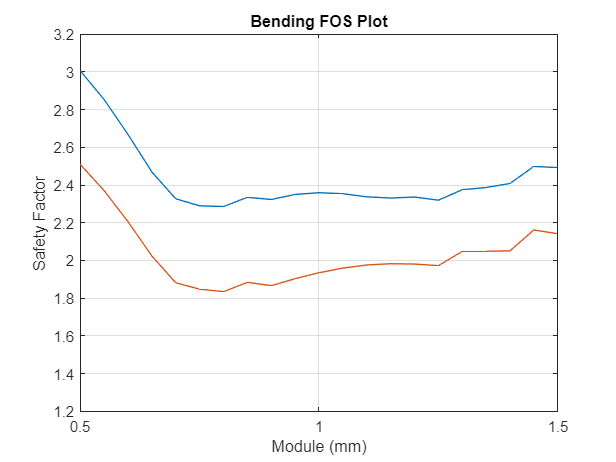

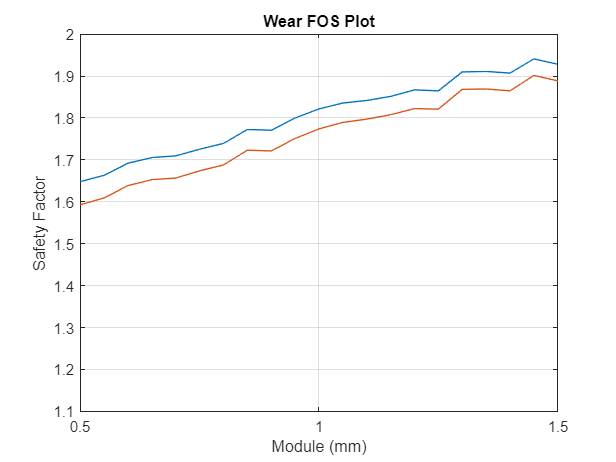

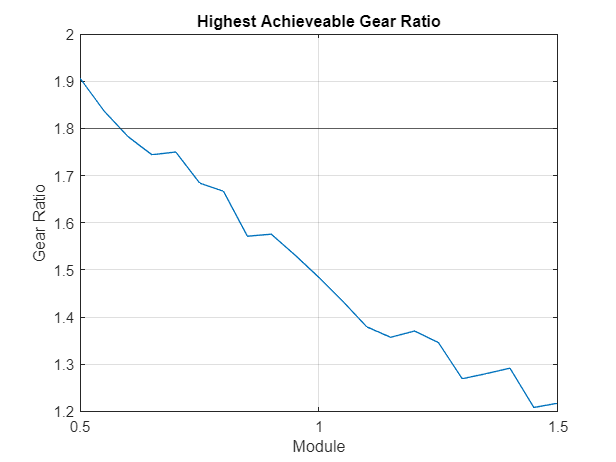

 
modules = modules(modules ~= excludevals);
sunTeeths = zeros(size(modules));

for i = 1:1:length(modules)
    sunTeeths(i) = minSunTeeth(20,modules(i),sun,motor);
end

sunPitchDiameters = modules.*sunTeeths;
planetTeeths = floor(2 * (target_center_dist - sunPitchDiameters/2)./modules);
planetPitchDiameters = planetTeeths .* modules;
actual_center_dist = (sunPitchDiameters + planetPitchDiameters)/2;

sun_safeties = struct('root',zeros(size(modules)),'flank',zeros(size(modules)));
planet_safeties = struct('root',zeros(size(modules)),'flank',zeros(size(modules)));
contact_ratios = zeros(size(modules));

for i = 1:1:length(modules)
    trial_sun.module = modules(i);
    trial_sun.teethNum = sunTeeths(i);
    trial_sun.pitchDiameter = sunPitchDiameters(i);
    trial_sun.facewidth = sun.facewidth;
    trial_sun.addendum = sun.addendum_factor * modules(i);
    trial_sun.wholeDepth = sun.whole_depth_factor * modules(i);
    trial_sun.deddendum = trial_sun.wholeDepth - trial_sun.addendum;
    trial_sun.pressureAngle = sun.pressureAngle;
    trial_sun.hardness = sun.hardness;

    trial_planetSunStage.module = modules(i);
    trial_planetSunStage.teethNum = planetTeeths(i);
    trial_planetSunStage.pitchDiameter = planetPitchDiameters(i);
    trial_planetSunStage.facewidth = planet.sunStage.facewidth;
    trial_planetSunStage.addendum = planet.sunStage.addendum_factor * modules(i);
    trial_planetSunStage.wholeDepth = planet.sunStage.whole_depth_factor * modules(i);
    trial_planetSunStage.deddendum = trial_planetSunStage.wholeDepth - trial_planetSunStage.addendum;
    trial_planetSunStage.pressureAngle = planet.sunStage.pressureAngle;
    trial_planetSunStage.hardness = planet.hardness;

    [sun_safety, planet_safety] = GearStress_PlanetSun(trial_sun,trial_planetSunStage,gearbox,motor,1 , 2.5, 25);
    sun_safeties.root(i) = sun_safety.root;
    sun_safeties.flank(i) = sun_safety.flank;
    planet_safeties.root(i) = planet_safety.root;
    planet_safeties.flank(i) = planet_safety.flank;
    contact_ratios(i) = getContactRatio(modules(i),sun.pressureAngle,trial_sun,trial_planetSunStage,actual_center_dist(i));
end

pass_criteria = struct('margin',...
                [planetTeeths./sunTeeths - target_gr;...
                 sun_safeties.flank - wear_safety_target ;...
                 gb_rad_lim - planetPitchDiameters+sunPitchDiameters/2;...
                 sun_safeties.root - bending_safety_target]);...
                 %contact_ratios - 1;...
                 %2 - contact_ratios]);

pass_criteria.nonDimMargin = pass_criteria.margin ./...
                            [target_gr;...
                             wear_safety_target;...
                             gb_rad_lim;...
                             bending_safety_target];
                             %1;
                             %1];

pass_criteria.labels = ["Gear Ratio",...
                        "Sun Wear Safety",...
                        "Overall radius limit",...
                        "Sun Bending Safety"];%,...
                        %"Low Contact Ratio",...
                        %"High Contact Ratio"];

essential_margin = pass_criteria.margin(2:end,:);
pass_criteria.pass = sum(essential_margin > 0,1) == size(essential_margin,1);


pass_criteria.weights = [1 1 2 2 ];%0 0];
 
weighted_criteria = pass_criteria.weights * pass_criteria.nonDimMargin;

pass_index = sum(pass_criteria.pass,1);
passed = modules(pass_index == size(pass_criteria.pass,1));

reduced_weighted_criteria =  weighted_criteria(:,pass_criteria.pass);
reduced_modules = modules(pass_criteria.pass);

clear("output_table");

if ~isempty(reduced_modules)
    output_table.goodness =  reduced_weighted_criteria';
    output_table.passed_modules =  reduced_modules';
    disp(struct2table(output_table))
    [~, reduced_best_index] = max(reduced_weighted_criteria);
    best_index = reduced_modules(reduced_best_index) == modules;
    
    
    effectiveInternalDiameter = 2 * sqrt((sun.internalDiameter / 2 + motor.keyProjHeight)^2 + (motor.keyWidth / 2)^2);
    sun_rim = sunPitchDiameters(best_index)/2 - modules(best_index)*(sun.whole_depth_factor-sun.addendum_factor) - 1000*effectiveInternalDiameter/2;
    
    fprintf(" \n \n \n \nBest Configuration:")
    fprintf("Module (mm): \t\t\t%.2f",modules(best_index))
    printFormatLine()
    fprintf(" \n \n")
    fprintf("Sun Gear:")
    printFormatLine()
    fprintf("Teeth: \t\t\t%d",sunTeeths(best_index))
    fprintf("Pitch Diameter (mm): \t%.2f",sunPitchDiameters(best_index))
    fprintf("Rim Thickness (mm): \t%.2f",sun_rim);
    fprintf(" \n \n \n \n")
    fprintf("Planet Gear:")
    printFormatLine()
    fprintf("Teeth: \t\t\t%d",planetTeeths(best_index))
    fprintf("Pitch Diameter (mm): \t%.2f",planetPitchDiameters(best_index))
    
    f1 =figure;
    plot(reduced_modules,planet_safeties.root(modules == reduced_modules),modules,sun_safeties.root);
    title("Bending FOS Plot")
    ylabel("Safety Factor")
    xlabel("Module (mm)")
    yline(bending_safety_target)
    grid on
    
    f2 = figure;
    plot(modules,planet_safeties.flank,modules,sun_safeties.flank);
    title("Wear FOS Plot")
    ylabel("Safety Factor")
    xlabel("Module (mm)")
    yline(wear_safety_target)
    grid on 
    
    f3 = figure;
    plot(modules,planetTeeths./sunTeeths)
    title("Highest Achieveable Gear Ratio")
    ylabel("Gear Ratio")
    xlabel("Module")
    yline(target_gr)
    grid on
    
else
    fprintf("No Solution Found")
    [~, closest_solution_index] = max(sum(pass_criteria.margin > 0,1));
    failed_criteria_index = find(pass_criteria.margin(:,closest_solution_index) <= 0);
    
    
    output_table.failed_criteria = pass_criteria.labels(failed_criteria_index)';
    output_table.relative_margin_of_failure = pass_criteria.margin(failed_criteria_index,closest_solution_index)';
    disp(struct2table(output_table))
end

function [min_sunteeth] = minSunTeeth(pressureAngle,module,sun,motor)
    backup_ratio = 1.2;
    deddendum_factor = sun.whole_depth_factor - sun.addendum_factor;
    tooth_height = sun.whole_depth_factor * module;
    rim_thickness = tooth_height * backup_ratio;
    effectiveInternalDiameter = 2 * sqrt((sun.internalDiameter / 2 + motor.keyProjHeight)^2 + (motor.keyWidth / 2)^2);
    pitchDiameter = 2 * (rim_thickness + deddendum_factor * module + 1000 * effectiveInternalDiameter / 2);
    min_sunteeth_rim = ceil(pitchDiameter / module);
    min_sunteeth_undercut = ceil(2 / (sind(pressureAngle))^2);
    min_sunteeth = max(min_sunteeth_rim,min_sunteeth_undercut);
end

function[] = printFormatLine()
    fprintf("--------------------------------------")
end